# Kalman Filtering

This case study illustrates Kalman filter design and simulation. Both steady-state and time-varying Kalman filters are considered.

## Plant Dynamics

Consider a discrete plant with additive Gaussian noise $w\left[ n \right]$ on the input $u\left[ n \right]$:


$$\begin{array}{l}
x\left[ {n + 1} \right] = Ax\left[ n \right] + B(u\left[ n \right] + w\left[ n \right])\\
y\left[ n \right] = Cx\left[ n \right].
\end{array}$$


Further, let ${y_v}\left[ n \right]$ be a noisy measurement of the output $y\left[ n \right]$, with $v\left[ n \right]$ denoting the measurement noise:


$${y_v}\left[ n \right] = y\left[ n \right] + v\left[ n \right].$$


The following matrices represent the dynamics of the plant.

A = [1.1269   -0.4940    0.1129;
     1.0000         0         0;
          0    1.0000         0];

B = [-0.3832;
      0.5919;
      0.5191];

C = [1 0 0];

## Discrete Kalman Filter

The equations of the steady-state Kalman filter for this problem are given as follows.

- Measurement update:


$$\hat x\left[ {n|n} \right] = \hat x\left[ {n|n - 1} \right] +
M({y_v}\left[ n \right] - C\hat x\left[ {n|n - 1} \right])$$


- Time update:


$$\hat x\left[ {n + 1|n} \right] = A\hat x\left[ {n|n} \right] + Bu\left[ n \right]$$


In these equations:

- $\hat x\left[ {n|n - 1} \right]$ is the estimate of $x\left[ n \right]$, given past measurements up to $y_{v}\left[ n - 1\right]$.

- $\hat x\left[ {n|n} \right]$ is the updated estimate based on the last measurement $y_{v}\left[ n\right]$. 

Given the current estimate $\hat x\left[ {n|n} \right]$, the time update predicts the state value at the next sample *n* + 1 (one-step-ahead predictor). The measurement update then adjusts this prediction based on the new measurement $y_{v}\left[ n + 1\right]$. The correction term is a function of the innovation, that is, the discrepancy between the measured and predicted values of $y\left[ n + 1\right]$. This discrepancy is given by:


$${y_v}\left[ {n + 1} \right] - C\hat x\left[ {n + 1\left| n \right.} \right]$$


The innovation gain M is chosen to minimize the steady-state covariance of the estimation error, given the noise covariances:


$$E\left( {w\left[ n \right]w{{\left[ n \right]}^T}} \right) = Q\quad
\quad E\left( {v\left[ n \right]v{{\left[ n \right]}^T}} \right) = R\quad
\quad N = E\left( {w\left[ n \right]v{{\left[ n \right]}^T}} \right) =
0$$


You can combine the time and measurement update equations into one state-space model, the Kalman filter:


$$\begin{array}{l} \hat x\left[ {n + 1\left| n \right.} \right] =
A\left( {I - MC} \right)\hat x\left[ {n\left| {n - 1} \right.} \right] +
\left[ {\begin{array}{*{20}{c}} B&{AM} \end{array}} \right]\left[
{\begin{array}{*{20}{c}} {u\left[ n \right]}\\ {{y_v}\left[ n \right]}
\end{array}} \right]\\ \hat y\left[ {\left. n \right|n} \right] = C\left(
{I - MC} \right)\hat x\left[ {n\left| {n - 1} \right.} \right] +
CM{y_v}\left[ n \right]. \end{array}$$


This filter generates an optimal estimate $\hat y\left[ {n|n} \right]$ of $y_{n}$. Note that the filter state is  $\hat x\left[ {n|n - 1} \right]$.

## Steady-State Design

You can design the steady-state Kalman filter described above with the function `kalman`. First specify the plant model with the process noise:


$$\begin{array}{*{20}{c}}
{x\left[ {n + 1} \right] = Ax\left[ n \right] + Bu\left[ n \right] + Bw\left[ n \right]}\\
{y\left[ n \right] = Cx\left[ n \right]}
\end{array}$$


Here, the first expression is the state equation, and the second is the measurement equation.

The following command specifies this plant model. The sample time is set to -1, to mark the model as discrete without specifying a sample time.

Plant = ss(A,[B B],C,0,-1,'inputname',{'u' 'w'},'outputname','y');

Assuming that *Q* = *R* = 1, design the discrete Kalman filter.

Q = 1; 
R = 1;
[kalmf,L,P,M] = kalman(Plant,Q,R);

This command returns a state-space model `kalmf` of the filter, as well as the innovation gain `M`.

M

The inputs of `kalmf` are *u* and $y_{v}$, and. The outputs are the plant output and the state estimates, $y_{e} = \hat y\left[ {n|n} \right]$ and $\hat x\left[ {n|n} \right]$.

Because you are interested in the output estimate $y_{e}$, select the first output of `kalmf` and discard the rest.

kalmf = kalmf(1,:);

To see how the filter works, generate some input data and random noise and compare the filtered response $y_{e}$ with the true response *y*. You can either generate each response separately, or generate both together. To simulate each response separately, use `lsim` with the plant alone first, and then with the plant and filter hooked up together. The joint simulation alternative is detailed next.

The block diagram below shows how to generate both true and filtered outputs.

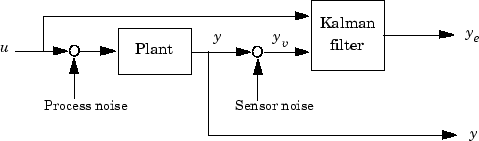

You can construct a state-space model of this block diagram with the functions `parallel` and `feedback`. First build a complete plant model with *u*, *w*, *v* as inputs, and *y* and $y_{v}$ (measurements) as outputs.

a = A;
b = [B B 0*B];
c = [C;C];
d = [0 0 0;0 0 1];
P = ss(a,b,c,d,-1,'inputname',{'u' 'w' 'v'},'outputname',{'y' 'yv'});

Then use `parallel` to form the parallel connection of the following illustration.

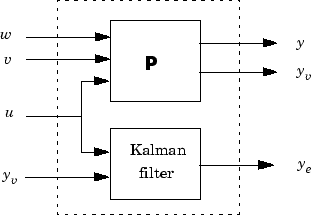

sys = parallel(P,kalmf,1,1,[],[]);

Finally, close the sensor loop by connecting the plant output $y_{v}$ to filter input $y_{v}$ with positive feedback. 

SimModel = feedback(sys,1,4,2,1);   % Close loop around input #4 and output #2
SimModel = SimModel([1 3],[1 2 3]); % Delete yv from I/O list

The resulting simulation model has *w*, *v*, *u* as inputs, and *y* and $y_{e}$ as outputs. View the `InputName` and `OutputName` properties to verify.

SimModel.InputName

SimModel.OutputName

You are now ready to simulate the filter behavior. Generate a sinusoidal input *u* and process and measurement noise vectors *w* and *v*.

t = [0:100]';
u = sin(t/5);

n = length(t);
rng default
w = sqrt(Q)*randn(n,1);
v = sqrt(R)*randn(n,1);

Simulate the responses.

[out,x] = lsim(SimModel,[w,v,u]);

y = out(:,1);   % true response
ye = out(:,2);  % filtered response
yv = y + v;     % measured response

Compare the true and filtered responses graphically.

subplot(211), plot(t,y,'--',t,ye,'-'), 
xlabel('No. of samples'), ylabel('Output')
title('Kalman filter response')
subplot(212), plot(t,y-yv,'-.',t,y-ye,'-'),
xlabel('No. of samples'), ylabel('Error')

The first plot shows the true response *y* (dashed line) and the filtered output $y_{e}$ (solid line). The second plot compares the measurement error (dash-dot) with the estimation error (solid). This plot shows that the noise level has been significantly reduced. This is confirmed by calculating covariance errors. The error covariance before filtering (measurement error) is:

MeasErr = y-yv;
MeasErrCov = sum(MeasErr.*MeasErr)/length(MeasErr)

The error covariance after filtering (estimation error) is reduced:

EstErr = y-ye;
EstErrCov = sum(EstErr.*EstErr)/length(EstErr)

## Time-Varying Kalman Filter

The time-varying Kalman filter is a generalization of the steady-state filter for time-varying systems or LTI systems with nonstationary noise covariance. 

Consider the following plant state and measurement equations.


$$\begin{array}{rcl}
x\left[ {n + 1} \right]&=&Ax\left[ n \right] + Bu\left[ n \right] + Gw\left[ n \right]\\
{y_v}\left[ n \right]&=&Cx\left[ n \right] + v\left[ n \right].
\end{array}$$


The time-varying Kalman filter is given by the following recursions:

- Measurement update:


$$\begin{array}{rcl}
\hat x\left[ {n|n} \right] &=& \hat x\left[ {n|n - 1} \right] + M\left[ n \right]({y_v}\left[ n \right] - C\hat x\left[ {n|n - 1} \right])\\
M\left[ n \right] &=& P\left[ {n|n - 1} \right]{C^T}{(R\left[ n \right] + CP\left[ {n|n - 1} \right]{C^T})^{ - 1}}\\
P\left[ {n|n} \right] &=& (I - M\left[ n \right]C)P\left[ {n|n - 1}
\right].
\end{array}$$


- Time update:


$$\begin{array}{rcl}
\hat x\left[ {n + 1|n} \right] & = & A\hat x\left[ {n|n} \right] + Bu\left[ n \right]\\
P\left[ {n + 1|n} \right] & = & AP\left[ {n|n} \right]{A^T} + GQ\left[ n
\right]{G^T}.
\end{array}$$


Here, $\hat x\left[ {n|n - 1} \right]$ and $\hat x\left[ {n|n} \right]$ are as described previously. Additionally:


$$\begin{array}{l}
Q\left[ n \right] = E(w\left[ n \right]w{\left[ n \right]^T})\\
R\left[ n \right] = E(v\left[ n \right]v{\left[ n \right]^T})\\
P\left[ {n|n} \right] = E(\left\{ {x\left[ n \right] - x\left[ {n|n} \right]} \right\}{\left\{ {x\left[ n \right] - x\left[ {n|n} \right]} \right\}^T})\\
P\left[ {n|n - 1} \right] = E(\left\{ {x\left[ n \right] - x\left[ {n|n -
1} \right]} \right\}{\left\{ {x\left[ n \right] - x\left[ {n|n - 1} \right]} \right\}^T}).
\end{array}$$


For simplicity, the subscripts indicating the time dependence of the state-space matrices have been dropped.

Given initial conditions $x\left[ {1|0} \right]$ and $P\left[ {1|0} \right]$, you can iterate these equations to perform the filtering. You must update both the state estimates $x\left[ {n|.} \right]$ and error covariance matrices $P\left[ {n|.} \right]$ at each time sample.

## Time-Varying Design

To implement these filter recursions, first generate noisy output measurements. Use the process noise `w` and measurement noise `v` generated previously.

sys = ss(A,B,C,0,-1);
y = lsim(sys,u+w);      
yv = y + v;

Assume the following initial conditions:


$$\begin{array}{*{20}{c}}
{x\left[ {1|0} \right] = 0,}&{P\left[ {1|0} \right]}
\end{array} = BQ{B^T}$$


Implement the time-varying filter with a `for` loop.

P = B*Q*B';         % Initial error covariance
x = zeros(3,1);     % Initial condition on the state
ye = zeros(length(t),1);
ycov = zeros(length(t),1); 

for i = 1:length(t)
  % Measurement update
  Mn = P*C'/(C*P*C'+R);
  x = x + Mn*(yv(i)-C*x);   % x[n|n]
  P = (eye(3)-Mn*C)*P;      % P[n|n]

  ye(i) = C*x;
  errcov(i) = C*P*C';

  % Time update
  x = A*x + B*u(i);        % x[n+1|n]
  P = A*P*A' + B*Q*B';     % P[n+1|n]
end

Compare the true and estimated output graphically.

subplot(211), plot(t,y,'--',t,ye,'-')
title('Time-varying Kalman filter response')
xlabel('No. of samples'), ylabel('Output')
subplot(212), plot(t,y-yv,'-.',t,y-ye,'-')
xlabel('No. of samples'), ylabel('Output')

The first plot shows the true response *y* (dashed line) and the filtered response $y_{e}$ (solid line). The second plot compares the measurement error (dash-dot) with the estimation error (solid).

The time-varying filter also estimates the covariance `errcov` of the estimation error $y - y_{e}$ at each sample. Plot it to see if your filter reached steady state (as you expect with stationary input noise).

subplot(211)
plot(t,errcov), ylabel('Error covar')

From this covariance plot, you can see that the output covariance did indeed reach a steady state in about five samples. From then on, your time-varying filter has the same performance as the steady-state version.

Compare with the estimation error covariance derived from the experimental data:

EstErr = y - ye;
EstErrCov = sum(EstErr.*EstErr)/length(EstErr)

This value is smaller than the theoretical value `errcov` and close to the value obtained for the steady-state design.

Finally, note that the final value $M \left[ n \right]$ and the steady-state value *M* of the innovation gain matrix coincide.

Mn

M

## Bibliography

[1] Grimble, M.J., *Robust Industrial Control: Optimal Design Approach for Polynomial Systems*, Prentice Hall, 1994, p. 261 and pp. 443-456. 

*Copyright 2015 The MathWorks, Inc.*